# Simple BLDC motor model

This is a simple brushless DC motor model. It has been written with the purpose of generate (approximate) motor performance charts given a few characteristics numbers and the operating voltage. Often manufacturers of small brushless motors, like those installed on flying model aircraft, do not provide performance charts, but only a few parameters and two or three propeller are suggested. If you want to match another torque load, maybe a propeller with different diameter and/or RPM, you may not know if the motor is suited for your application. Therefore, without going deep into motor details and simulation, the three motor constants $K_v$ (RPM/Volt), $I_0$ (no-load current), and $R_m$ (windings resistance) should be sufficient to provide steady state performance data.

Therefore, this model needs the following inputs:

- operating voltage $V$, chosen by the user

- the $K_v$ constant, in RPM/Volt

- the no-load current $I_0$, in Ampere

- the internal resistance $R_m$, in Ohm

## The mathematical model in detail

The model is based on a power balance:


$$P_\text{electric} - P_\text{copper} - P_\text{iron} = P_\text{shaft}$$


that is, the shaft power, i.e. the power moving the load (propeller) on the shaft, is equal to the motor electric power minus the copper and the iron losses. The copper losses are due to the heat wasted by the internal resistance of the windings (Ohm's law), the iron losses are due to the no-load current, i.e. the current circulating in the motor without an applied load on the shaft.

The electric power is simply the applied voltage times the current absorbed by the motor:

    
$$P_\text{electric} = VI$$


The copper losses are the internal resistance times the square of the motor current:

    
$$P_\text{copper} = R_m I^2$$


The iron losses are the operating voltage times the no-load current:

    
$$P_\text{iron} = VI_0$$


The shaft power can be expressed in several ways. By assuming a propeller as motor load, we can write:

    
$$P_\text{shaft} = Q(\omega) \,\omega$$


that is a torque $Q$, function of the angular velocity $\omega$, times the angular velocity itself $\omega$.

In principle, the angular velocity may calculated with the motor constant $K_v$ (in opportune units, since $\omega$ is in rad/s):

    
$$\omega_0 = K_v \, V$$


but since the applied load will increase the current absorption reducing the useful (shaft) power, the angular speed will also reduce, hence $\omega_0 \ne \omega$. We assume this model:

    
$$\omega = K_v (V - R_mI)$$


that is the angular speed is linearly decreasing with the motor current, which is an expected result.

By detailing the power balance equation with all the useful terms we get:


$$VI - R_m I^2 - P_\text{iron} = P_\text{shaft}$$


where the iron losses and the shaft power are left as known terms. By rewriting this equation in the only unknown $I$ we get:


$$R_m I^2 - VI + (P_\text{iron} - P_\text{shaft}) = 0$$


that is a quadratic equation which the physical solution is the smaller root:


$$I = \frac{V - \sqrt{V^2 -  4 R_m (P_\text{iron} + P_\text{shaft})}} {2 R_m}$$


Also, the solution is physical if the discriminant is greater or equal than zero. That's why we treat $P_\text{shaft}$ as a known term. We are interested in motor performance chart, not to a single value of the applied load. Therefore, we calculate the current $I$ for an array of $P_\text{shaft}$ varying from zero to its maximum possible value, which is:

 
$$V^2 -  4 R_m (P_\text{iron} + P_\text{shaft}) = 0 \quad \longrightarrow \quad P_\text{shaft max} = \frac{V^2}{4 R_m} - VI_0$$


Hence, the shaft power is varied as:


$$0 \le P_\text{shaft} < P_\text{shaft max}$$


(theoretically the shaft power could be equal to its maximum, but numerically the discretization error may give imaginary solutions, so in the MATLAB code we stop at 99.9% of this maximum value)

Once known the motor current $I$ we can calculate all the other parameters of interest, in particular the electric power, the angular speed, the motor efficiency, and the useful torque. The equations for the first two quantities have been presented before. The last two quantities are simply:

    $\text{eff} = \frac{P_\text{shaft}}{P_\text{electric}}$    and    $Q = \frac{P_\text{shaft}}{\omega}$

## The MATLAB live script

Here the user assigns the motor constants and change the operating voltage to get live update of the charts.

The max current *Imax* field is not mandatory, but it is useful to limit the x-axis plot range. Therefore, the user may input the value of interest, even less that the value issued by the motor manufacturer.

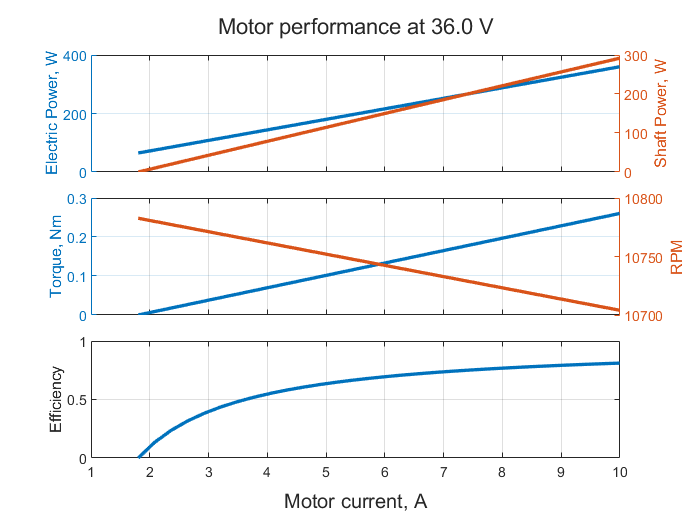

Kv = 300; % Kv, Volt/RPM
I0 = 1.8; % I0, Ampere
Rm = 0.032; % Rm, Ohm
Imax = 10; % max current, Ampere (useful to limit the axis)

V =36; % Voltage, V

[Imot, Pmot, Pload, Qload, omega, eff] = motorCalc(V,Kv,I0,Rm,Imax);
RPM = omega*60/(2*pi);

t = tiledlayout(3,1);
ax1 = nexttile;
yyaxis left
plot(Imot,Pmot,'LineWidth',2)
ylabel('Electric Power, W')
%
yyaxis right
plot(Imot,Pload,'LineWidth',2)
ylabel('Shaft Power, W')
grid on

ax2 = nexttile;
yyaxis left
plot(Imot,Qload,'LineWidth',2)
ylabel('Torque, Nm')
%
yyaxis right
plot(Imot,RPM,'LineWidth',2)
ylabel('RPM')
ax2.YAxis(2).Exponent = 0;
% ytickformat('%.0f')
grid on


ax3 = nexttile;
plot(Imot,eff,'LineWidth',2)
grid on
ylabel('Efficiency')

linkaxes([ax1,ax2,ax3],'x');
xticklabels([ax1,ax2],{})
xlabel(t,'Motor current, A')
title(t,['Motor performance at ',num2str(V,'%.1f'),' V'])
t.TileSpacing = 'compact';

#### License

    Copyright (C) 2021 Danilo Ciliberti danilo.ciliberti@unina.it

    This program is free software: you can redistribute it and/or modify

    it under the terms of the GNU General Public License as published by

    the Free Software Foundation, either version 3 of the License, or

    (at your option) any later version.

    This program is distributed in the hope that it will be useful,

    but WITHOUT ANY WARRANTY; without even the implied warranty of

    MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

    GNU General Public License for more details.

    You should have received a copy of the GNU General Public License

    along with this program.  If not, see <https://www.gnu.org/licenses/>